function gps = Task_gpsDecode(Instrument, Node, ReadType)

    gps = struct('Status',     0, 'Latitude',  -1, ...
                 'Longitude', -1, 'TimeStamp', []);
    
    flushinput(Instrument)

GPS embarcado no receptor fabricado pela R&S, modelo **EB500**. Ao enviar a requisição ':SYSTem:GPS:DATA?', obtém-se uma *string* de um conjunto de duas possíveis *strings*.

- Uma *string* vazia **''** (caso não haja conectividade); ou

- Uma *string* com o *template* **'GPS,1,1629933835,74,11,S,18,53,19.70,W,48,13,50.99,2021,8,25,23,23,55,0.00,0.00,338.50,940.00,1,-8.00'.**

    if contains(Node, 'EB500')
        gpsStr = deblank(query(Instrument, ':SYSTem:GPS:DATA?'));
        
        if ~isempty(gpsStr) && contains(gpsStr, 'GPS')
            gpsStr = strsplit(gpsStr, ',');
                        
            gps.Status = str2double(gpsStr{2});
            if gps.Status
                gps.Latitude = str2double(gpsStr{7}) + str2double(gpsStr{8})/60 + str2double(gpsStr{9})/3600;
                if strcmp(gpsStr{6}, 'S'); gps.Latitude = -gps.Latitude;
                end
                
                gps.Longitude = str2double(gpsStr{11}) + str2double(gpsStr{12})/60 + str2double(gpsStr{13})/3600;
                if strcmp(gpsStr{10}, 'W'); gps.Longitude = -gps.Longitude;
                end
                
                if strcmp(ReadType, 'Full')
                    gps.TimeStamp = datetime([str2double(gpsStr{14}), str2double(gpsStr{15}), str2double(gpsStr{16}), ...
                                              str2double(gpsStr{17}), str2double(gpsStr{18}), str2double(gpsStr{19})], 'Format', 'dd/MM/yyyy HH:mm:ss');
                end
            end
        end
        

GPS embarcado no analisador de espectro fabricado pela Anritsu, modelo **MS2720T**. Ao enviar a requisição ':FETCh:GPS?', obtém-se uma *string* de um conjunto de três possíveis *strings*.

- Uma *string* vazia **''** (caso não haja conectividade);

- Uma *string* **'NO FIX'** (caso não exista informação válida); ou

- Uma *string* com o *template* **'GOOD FIX,WED AUG 25 23:10:29 2021,-0.2267732173,-0.6713082194'** (caso exista informação válida).

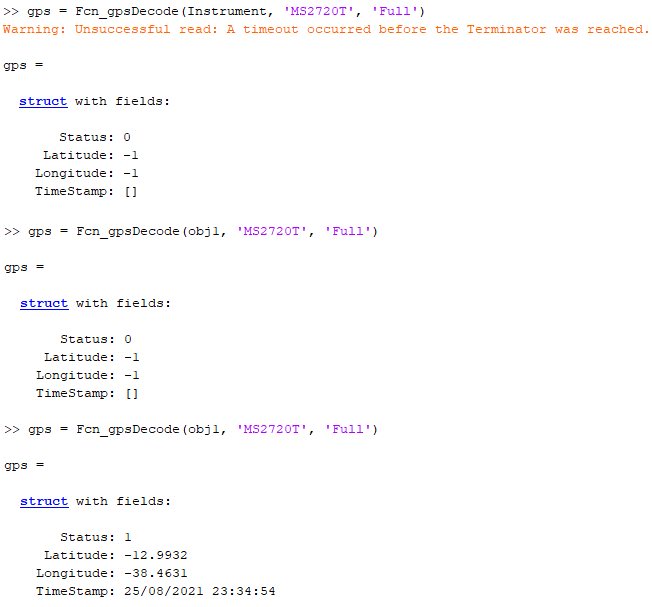

    elseif contains(Node, 'MS2720T')
        gpsStr = deblank(query(Instrument, ':FETCh:GPS?'));
        
        if ~isempty(gpsStr) && contains(gpsStr, 'GOOD FIX')
            gpsStr = strsplit(gpsStr, ',');
            
            gps.Status    = 1;
            gps.Latitude  = str2double(gpsStr{3})*180/pi;
            gps.Longitude = str2double(gpsStr{4})*180/pi;
            
            if strcmp(ReadType, 'Full')
                gps.TimeStamp = datetime(gpsStr{2}, "InputFormat", "eee MMM dd HH:mm:ss yyyy", 'Format', 'dd/MM/yyyy HH:mm:ss');
            end
        end
                

 GPS embarcado no analisador de espectro fabricado pela KeySight, modelo **N9344C**. Ao enviar a requisição ':SYSTem:GPSinfo?', obtém-se uma *string* de um conjunto de três possíveis *strings*.

- Uma *string* vazia **''** (caso não haja conectividade);

- Uma *string* com o *template* **'-38.463093,-12.993198,40,08252021,21:11:50'** (caso exista informação válida); ou

- Uma *string* **'0.000000,0.000000,0,02152009,00:12:19'** (caso não exista informação válida).

    elseif contains(Node, 'N9344C')
        gpsStr = deblank(query(Instrument, ':SYSTem:GPSinfo?'));
        
        if ~isempty(gpsStr) && ~contains(gpsStr, '0.000000')
            gpsStr = strsplit(gpsStr, ',');
            
            gps.Status    = 1;
            gps.Latitude  = str2double(gpsStr{2});
            gps.Longitude = str2double(gpsStr{1});
            
            if strcmp(ReadType, 'Full')
                gps.TimeStamp = datetime(sprintf('%s %s', gpsStr{4}, gpsStr{5}), "InputFormat", "MMddyyyy HH:mm:ss", 'Format', 'dd/MM/yyyy HH:mm:ss');
            end
        end
        

 GPS embarcado no analisador de espectro fabricado pela KeySight, modelo **N9936B**. Ao enviar a requisição ':SYSTem:GPS:DATA?', obtém-se uma *string* de um conjunto de três possíveis *strings*.

- Uma *string* vazia **''** (caso não haja conectividade);

- Uma *string* com o *template* **'"12 51.63421 S,38 18.50857 W,26,2021-08-27 19:29:34Z"'** (caso exista informação válida); ou

- Uma *string* **'"0,0,0,2021-08-27 19:33:18Z"'** (caso não exista informação válida).

    elseif contains(Node, 'N9936B')
        gpsStr = extractBetween(query(Instrument, ':SYSTem:GPS:DATA?'), '"', '"');
        
        if ~isempty(gpsStr) && ~contains(gpsStr{1}, '0,0,0')
            gpsStr = strsplit(gpsStr{1}, ',');
            
            gps.Status    = 1;
            
            Latitude     = strsplit(gpsStr{1}, ' ');
            gps.Latitude = str2double(Latitude{1}) + str2double(Latitude{2})/60;
            if strcmp(Latitude{3}, 'S'); gps.Latitude = -gps.Latitude;
            end
            
            Longitude     = strsplit(gpsStr{2}, ' ');
            gps.Longitude = str2double(Longitude{1}) + str2double(Longitude{2})/60;
            if strcmp(Longitude{3}, 'W'); gps.Longitude = -gps.Longitude;
            end
            
            if strcmp(ReadType, 'Full')
                gps.TimeStamp = datetime(gpsStr{4}(1:end-1), "InputFormat", "yyyy-MM-dd HH:mm:ss", 'Format', 'dd/MM/yyyy HH:mm:ss');
            end
        end
    end

end